Closed-loop Eigenvalue Assignment for a Discrete-Tme Aircraft Model

clear all; close all; clc

  Continuous-Time Model State Space Matrices

Ac=[-1.01887 0.90506 -0.00215 0 0;
    0.82225 -1.07741 -0.17555 0 0;
    0 0 -20.2 0 0;
    10 0 0 -10 0;
    0 -57.2958 0 0 0];
Bc=[0 0 20.2 0 0]';
Cc=[0 0 0 -57.2958 0; 0 -57.2958 0 0 0; 0 0 0 0 1];
Dc=[0 0 0]';

Sampling period Ts

Ts=0.05

Ts = 0.0500

sysc=ss(Ac,Bc,Cc,Dc);
sysd=c2d(sysc,Ts,'zoh');

Discrete-Time Model State Space Matrices

[Ad,Bd,Cd,Dd]=ssdata(sysd);
x0=[1 2 -1 3 -1]';

Desired closed-loop eigenvalue assignment placed within the unit circle 

p1 = 0.77

p1 = 0.7700

p2 = 0.83

p2 = 0.8300

p3 = 0.92

p3 = 0.9200

p4 = 0.82

p4 = 0.8200

p5 = 0.63

p5 = 0.6300

desired_ev=[p1 p2 p3 p4 p5];
Fd=place(Ad,Bd,desired_ev);

Calling the Simulink model "airplane.mdl" from the Life Script "evalue_assignment.mlx"

model=sim(aircraft);

Plotting the state variables returned by Simulink

time = [0:Ts:Ts*(length(model.tout)-1)];

In Simulink, if discrete-time is marked, the scope block will use stairs() rather than plot()

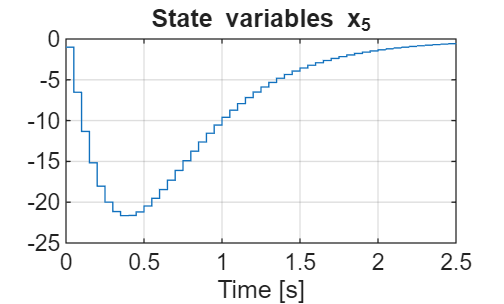

figure(1)
stairs(time,model.xd(:,1))
grid; xlabel('Time [s]'); title('State variables x_1');
figure(2)
stairs(time,model.xd(:,2))
grid; xlabel('Time [s]'); title('State variables x_2');
figure(3)
stairs(time,model.xd(:,3))
grid; xlabel('Time [s]'); title('State variables x_3');
figure(4)
stairs(time,model.xd(:,4))
grid; xlabel('Time [s]'); title('State variables x_4');
figure(5)
stairs(time,model.xd(:,5))
grid; xlabel('Time [s]'); title('State variables x_5');